#  Grid Code Compliance Report

## Overview

This report evaluates renewable plant simulation data against selected grid code standards. It performs automated checks on:

    - Steady-state voltage and frequency stability

    - Harmonics content (THD, individual harmonics)

    - Fault Ride Through (FRT) for voltage/frequency excursions

    - Reactive power capability based on PQ and QV curves

Requirements are derived from standards like IEEE 2800, ENTSO-E, AEMO, CEA. All thresholds and requirements are generalized approximation**s** that reflect common industry practice.

This live script provides the grid code assessment for a Photo Voltaic (PV) plant integrated with a Battery Energy Storage System (BESS). To execute the grid code tests first load this model [PVBESSGridCodeTest.slx](matlab:open('..\..\Models\GridCodeChecks\TestonBESSPVPlant.slx')) . 

## Steps for Grid Code Assessment

### Select Grid Code and Frequency

You can use the dropdown given below to select a grid code and the system frequency to check compliance.

% Select grid code
gridCodeName = "IEEE2800"; % Choose from supported codes (e.g., 'ENTSOE', 'CEA', 'AEMO')
% Select system frequency in Hz
systemFrequency = 60; % System base frequency in Hz (e.g., 50 or 60 Hz)
% Fetch threshold specifications for voltage, frequency, harmonics, FRT, etc.
gridCode = getGridCode(gridCodeName);

  % Press this button to run this live script

### Select Measurement Window

%% Measurement window to perform test
t1 = 1; 
t2 = 5; % t1 and t2 are in sec, optional parameters

### **Generated Reference for Testing**

Initializes a test signal generator that produces voltage, frequency, active/reactive power time-series signals used to simulate disturbances, ramps, and transitions, ensuring the plant can respond appropriately to grid events.

ts = 0.001; % Sampling time of test signals
reference = DynamicSignalGenerator(ts);  % Signal generation for test cases
% Saving signals in a .mat file for using in simulations
reference.exportForSignalEditor("TestSignals.mat");

✅ Exported to "TestSignals.mat" for Simulink Signal Editor


### **Flat Run Check **( Use any steady-state data)

For flat run test you need to simulate the model with flat voltage, frequency, and power profiles.

#### **Configure all signals for a flat run**

testPr = reference.Flat; % Real power for flat start (1 pu)
testQr = 0.1*reference.Flat; %#ok<*NASGU> % Reactive power for flat start (0.1 pu)
testVg = reference.Flat; % Grid voltage for flat start (1 pu)
testF = 60*reference.Flat; % Grid frequency (Hz)

#### Simulation Settings

You capture the output signals from the point of interconnection (POI) of your simulation model, using the measurement block provided in the project. The measured signals includes: voltage magnitude, frequency, real power (P), reactive power (Q), and three-phase voltage and current waveform. 

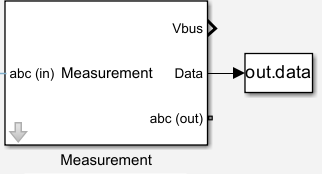

They are stored in the workspace variable `'out.data'`.

**Simulate Model**

SimulationTime = t2; % Simulation duration in (sec)
flatrun = sim(bdroot); % Simulate model

measurements = flatrun.data; % Measurements for the simulated scenario

Create a test object, `testCode, `of class` gridCodeComplianceChecker,` to test the measured data against the selected grid code.

testCode = gridCodeComplianceChecker(measurements, gridCode, systemFrequency, "t1", t1, "t2", t2);

#### Steady State Voltage Compliance Test

The voltage compliance check verifies that the voltage magnitude remains within the acceptable limits defined by the grid code. Deviations beyond these limits may indicate instability or equipment issues.

testCode = checkVoltage(testCode); % Check for voltage limit violations 

Voltage Compliance: ✅ PASS


#### Steady State Frequency Compliance Test

The frequency compliance check ensures that the system frequency stays within the grid code’s specified range. Stable frequency is critical for grid reliability and equipment operation.

testCode = checkFrequency(testCode); % Check for frequency limit violations

Frequency Compliance: ✅ PASS


#### Plots For Flat Run

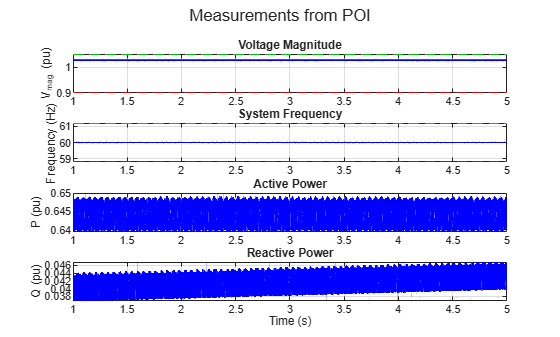

testCode.plotSignals;

#### Harmonics Compliance

The harmonics check analyzes the harmonic content of current and voltage signals. Excessive harmonics can degrade power quality and affect equipment longevity. The harmonic compliance are tested during steady state.

Total Harmonic Distortion (THD) and individual harmonic limits are evaluated.

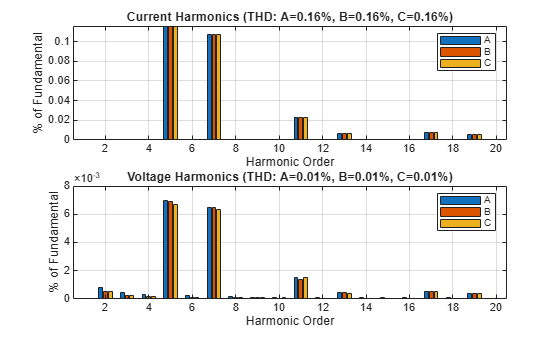

Maximum THD (Current): 0.16 % | Maximum THD (Voltage): 0.01 %
Harmonics Compliance: ✅ PASS


testCode = checkHarmonics(testCode); % Check for harmonic limit violations

### Voltage Frequency Ride-Through (FRT) Compliance

The FRT check assesses the system’s ability to withstand voltage and frequency excursions (e.g., faults, sags or swells) without tripping, as required by the grid code. This is crucial for maintaining grid stability during faults.

This test evaluates the dynamic voltage response of the renewable energy plant under fault conditions to ensure compliance with the Low Voltage Ride Through (LVRT) and Over Voltage Ride Through (OVRT) requirements.

%% Measurement window to perform test
t1 = 1; 
t2 = 7; % t1 and t2 are in sec, optional parameters

#### **Configure all signals for a LVRT Test**

testPr = reference.Flat;
testQr = 0.01*reference.Flat;
testVg = reference.Vdip;
testF = 60*reference.Flat;
SimulationTime = t2;

You can simulate a fault scenario by creating a voltage dip at the grid terminals. 

This figure shows a low-voltage event at the grid mimicking a fault, used to validate the plant’s ability to stay connected during and recover after voltage dips as per grid code ride-through requirements.

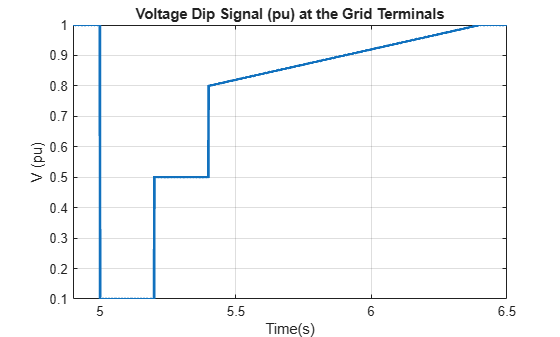

% Plot Reference Voltage Dip Signal
figure;
plot(testVg, 'LineWidth', 2); title('Voltage Dip at Grid'); ylabel('V (pu)'); xlabel('Time(s)'); title('Voltage Dip Signal (pu) at the Grid Terminals');xlim([4.9 6.5]); grid on;

**Simulate Model**

VdipRun = sim(bdroot); % Simulate model

% Update measurements for test case
testCode = updateData(testCode, VdipRun.data, "t1", t1, "t2", t2);

✅ Data updated. Samples: 120001 | Duration: 6.00 s


#### Run Tests

The objective is to verify that the plant remains connected and operational during voltage disturbances, specifically:

- Voltage dips below nominal (LVRT region)

- Voltage overshoots above nominal (OVRT region)

- Recovery behavior post-fault

testCode = checkVoltageRideThrough(testCode); % Check for voltage ride-through violations


[Voltage Ride-Through Test with Power Recovery]
✔ No violation @ 1.20 pu
✔ No violation @ 1.10 pu
✔ No violation @ 1.05 pu
✅ FRT-Voltage @ 0.90 pu/Hz | Duration: 0.75 s (Limit: 1.50 s)
✅ FRT-Voltage @ 0.70 pu/Hz | Duration: 0.40 s (Limit: 0.70 s)
✔ FRT-Voltage @ 0.45 pu/Hz | Duration: 0.20 s (Limit: 0.15 s)
✔ No violation @ 0.00 pu
❌ Power Recovery | P: 0.640 → 0.647 (1.0%), Q: -0.002 → -0.001 (68.9%)


testCode = checkFrequencyRideThrough(testCode); % Check for frequency ride-through violations


[Frequency Ride-Through Test]
✅ FRT-Frequency @ 57.00 pu/Hz | Duration: 0.00 s (Limit: 10.00 s)
✅ FRT-Frequency @ 59.00 pu/Hz | Duration: 0.05 s (Limit: 300.00 s)
✅ FRT-Frequency @ 61.00 pu/Hz | Duration: 0.04 s (Limit: 300.00 s)
✅ FRT-Frequency @ 63.00 pu/Hz | Duration: 0.02 s (Limit: 10.00 s)


#### Plots For LVRT and FRT

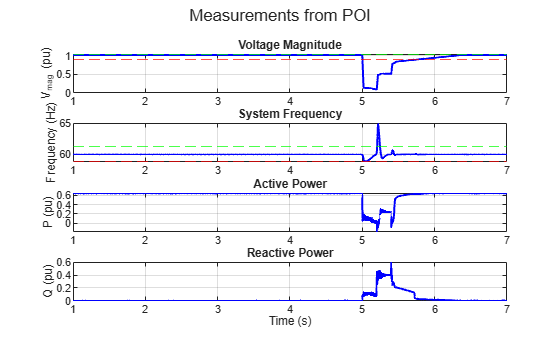

plotSignals(testCode);

#### Compliance Visualizations

The following plots show frequency, current, and voltage waveform over time, with non-compliant regions highlighted. These visualizations help identify where and when the system deviates from grid code requirements.

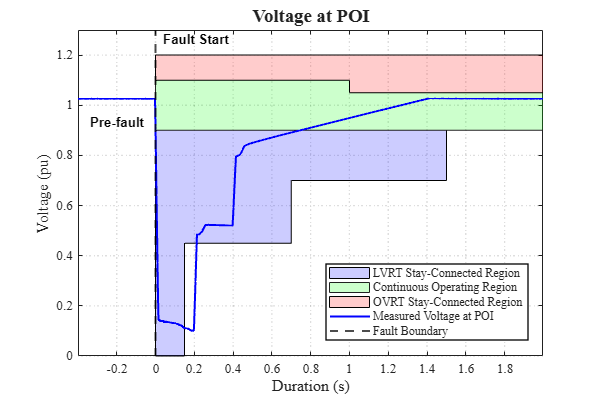

plotLVRTFRTCompliance(testCode); % Generate plots

This plot illustrates the Low Voltage Ride Through (LVRT) and Over Voltage Ride Through (OVRT) compliance of a renewable energy system based on measured voltage at the Point of Interconnection (POI).

The time axis starts by showing pre-disturbance conditions leading into the voltage dip event, the 0-second mark is aligned with the start of the voltage violation (e.g., fault inception).

### **Reactive Power Capability Tests**

 This test evaluates whether the renewable energy generation system can provide or absorb reactive power (Q) across a range of operating conditions. The capability to control Q helps maintain grid voltage levels and supports system stability.

#### **Reactive Power Capability for Real Power (PQ Curves)**

Ensures the plant operates within the allowable P-Q envelope, validating active/reactive capability delivery under dynamic conditions.

%% Measurement window to perform test
t1 = 1; 
t2 = 10; % t1 and t2 are in sec, optional parameters

**Configure all signals**

% Simulate for PQ compliance
testVg = reference.Flat;
testF = 60*reference.Flat;
testPr = reference.PQcapability.P;
testQr = reference.PQcapability.Q;
SimulationTime = t2;

**Simulate Model**

PQRun = sim(bdroot);

% Update measurements for test case
testCode = updateData(testCode, PQRun.data, "t1", t1, "t2", t2);

✅ Data updated. Samples: 180001 | Duration: 9.00 s


#### **Test Inputs**

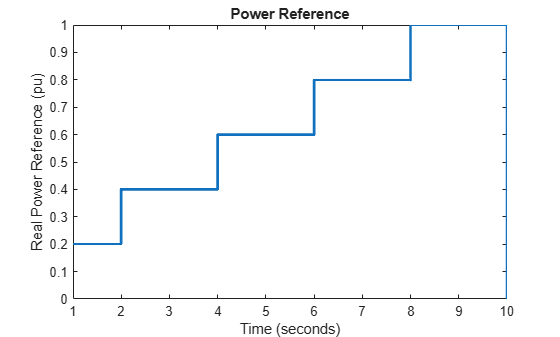

figure; 
plot(reference.PQcapability.P, 'LineWidth', 2); ylabel('Real Power Reference (pu)'); xlim([t1 t2]); title('Power Reference');

#### **Test Result**

testCode = testPQCapability(testCode, reference);


[PQ Capability Check — Based on Reference P Steps]
✔ Step  1 | P = 0.339, Q = 0.002 → Within limits
✔ Step  2 | P = 0.422, Q = 0.009 → Within limits
✔ Step  3 | P = 0.507, Q = 0.020 → Within limits
✔ Step  4 | P = 0.598, Q = 0.071 → Within limits
✔ Step  5 | P = 0.644, Q = -0.004 → Within limits
PQ Capability (Reference-Based): ✅ PASS


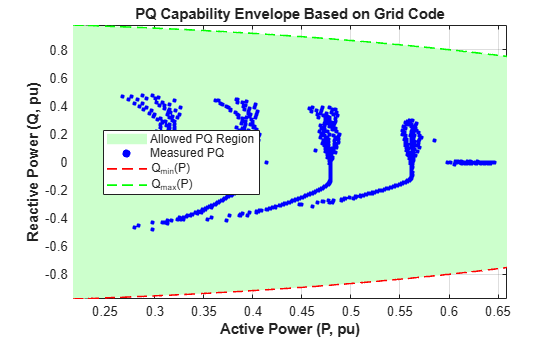

plotPQCapabilityEnvelope(testCode);

#### **Reactive Power Capability for Voltage Support (QV Curves)**

Checks compliance to the QV characteristic defined by the grid code, validating the inverter-based resource's voltage-reactive power control performance.

% Simulate for PQ compliance
testVg = reference.QVcapability.V;
testF = 60*reference.Flat;
testPr = reference.Flat;
testQr = reference.Flat;

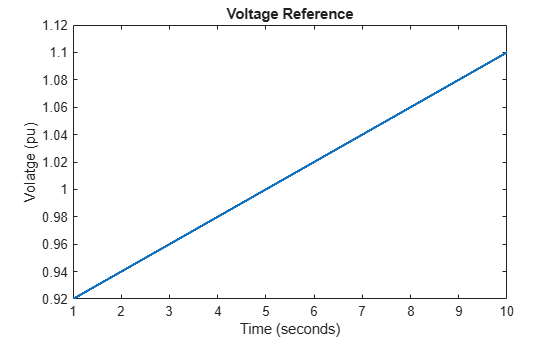

figure; 
plot(reference.QVcapability.V, 'LineWidth', 2); ylabel('Volatge (pu)'); xlim([t1 t2]); title('Voltage Reference');

**Simulate Model**

QVRun = sim(bdroot);

% Update measurements for test case
testCode = updateData(testCode, QVRun.data, "t1", t1, "t2", t2);

✅ Data updated. Samples: 180001 | Duration: 9.00 s


#### **Test Inputs**

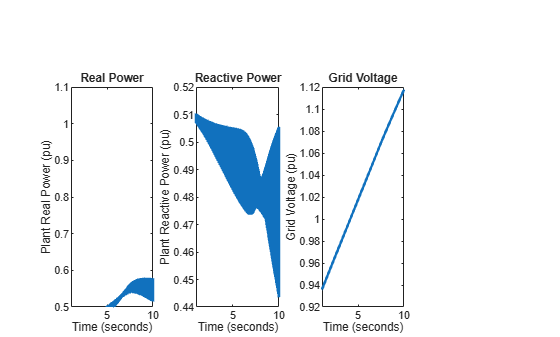

figure; 
subplot(1,3,1); plot(QVRun.data.P, 'LineWidth', 2); ylabel('Plant Real Power (pu)'); xlim([t1 t2]); ylim([0.5 1.1]); title('Real Power');
subplot(1,3,2); plot(QVRun.data.Q, 'LineWidth', 2); ylabel('Plant Reactive Power (pu)'); xlim([t1 t2]); title('Reactive Power');
subplot(1,3,3); plot(QVRun.data.Vmag, 'LineWidth', 2); ylabel('Grid Voltage (pu)'); xlim([t1 t2]); title('Grid Voltage');

#### Test Results

testCode = testQVCapability(testCode, reference);


[QV Capability Check — Based on Reference Voltage Steps]
✔ Time 1.0 | V = 0.936, Q = 0.508 → Within limits
✔ Time 1.5 | V = 0.946, Q = 0.506 → Within limits
✔ Time 2.0 | V = 0.957, Q = 0.504 → Within limits
✔ Time 2.5 | V = 0.967, Q = 0.503 → Within limits
✔ Time 3.0 | V = 0.977, Q = 0.501 → Within limits
✔ Time 3.5 | V = 0.988, Q = 0.500 → Within limits
✔ Time 4.0 | V = 0.998, Q = 0.498 → Within limits
❌ Time 4.5 | V = 1.008, Q = 0.497 → Outside [-1.000, -0.020]
❌ Time 5.0 | V = 1.018, Q = 0.495 → Outside [-1.000, -0.046]
❌ Time 5.5 | V = 1.029, Q = 0.493 → Outside [-1.000, -0.071]
❌ Time 6.0 | V = 1.039, Q = 0.492 → Outside [-1.000, -0.097]
❌ Time 6.5 | V = 1.049, Q = 0.489 → Outside [-1.000, -0.144]
❌ Time 7.0 | V = 1.059, Q = 0.488 → Outside [-1.000, -0.193]
❌ Time 7.5 | V = 1.070, Q = 0.486 → Outside [-1.000, -0.241]
❌ Time 8.0 | V = 1.080, Q = 0.485 → Outside [-1.000, -0.288]
❌ Time 8.5 | V = 1.089, Q = 0.483 → Outside [-1.000, -0.329]
❌ Time 9.0 | V = 1.099, Q = 0.483 → Outside

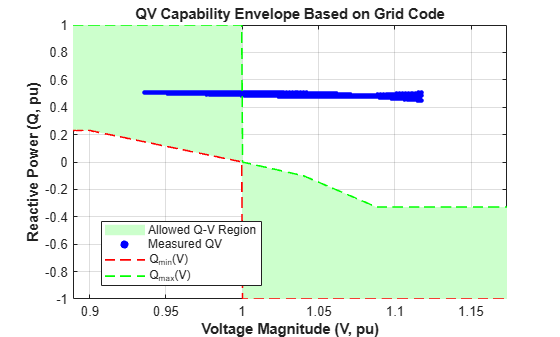

plotQVCapabilityEnvelope(testCode);

## Summary of Compliance Checks

The summary table consolidates the results of all dynamic performance tests (Voltage, Frequency, Fault Ride-Through, Harmonics, and Reactive Power capability) into a single view.

summaryTable(testCode);

--- Grid Code Compliance Summary ---
        Category        Compliance
    ________________    __________

    {'Voltage'     }      {'✅'}  
    {'Frequency'   }      {'✅'}  
    {'Harmonics'   }      {'✅'}  
    {'FRT'         }      {'❌'}  
    {'FRT_Freq'    }      {'✅'}  
    {'PQCapability'}      {'✅'}  
    {'QVCapability'}      {'❌'}  



Copyright 2025 - 2026 The MathWorks, Inc.